# Descending Schlogl 

Read reaction network

filnam = "2Schlogl"

filnam = "2Schlogl"

model_nam = "2Schlogl"

model_nam = "2Schlogl"

[num_spec,species,comp_vec,rxn_rate,G] = extract_rxn_net(filnam);

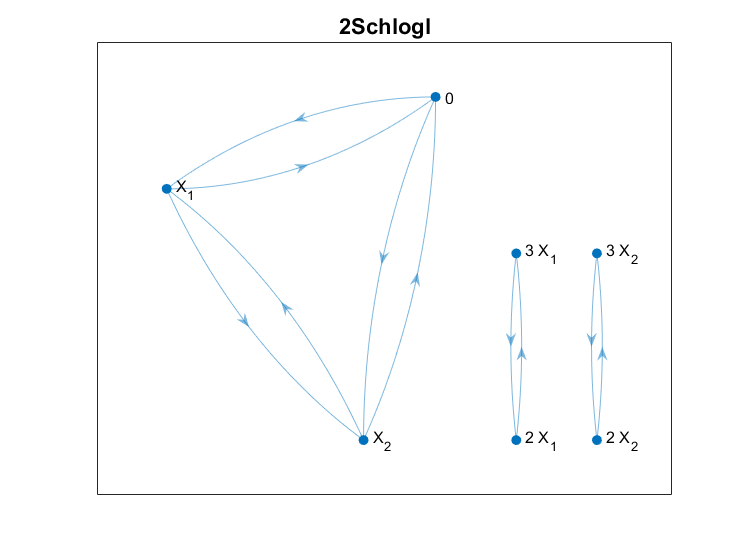

plotter(G,model_nam)
saveas(gcf,'Examples\Plots\'+ model_nam + '_hypergraph.png')

%Get Hamiltonian
Ham = get_Hamiltonian(num_spec,comp_vec,rxn_rate)

$$Ham = 6\,{\mathrm{e}}^{p_{1}}+6\,{\mathrm{e}}^{p_{2}}+q_{1}\,\left(0.1500\,{\mathrm{e}}^{p_{2}-p_{1}}-0.1500\right)+q_{2}\,\left(0.1500\,{\mathrm{e}}^{p_{1}-p_{2}}-0.1500\right)+q_{1}\,\left(11\,{\mathrm{e}}^{-p_{1}}-11\right)+q_{2}\,\left(11\,{\mathrm{e}}^{-p_{2}}-11\right)+{q_{1}}^{3}\,\left({\mathrm{e}}^{-p_{1}}-1\right)+{q_{2}}^{3}\,\left({\mathrm{e}}^{-p_{2}}-1\right)+{q_{1}}^{2}\,\left(6\,{\mathrm{e}}^{p_{1}}-6\right)+{q_{2}}^{2}\,\left(6\,{\mathrm{e}}^{p_{2}}-6\right)-12$$


%get functions derived from the Hamiltonian needed for the descent
Extract_Hamiltonian

%Get MAK polynomials and the jacobian
[MAK, jac, MAK_fun, jac_fun] = get_MAK(dHamdp,Ham_qp_mix,num_spec);

$$MAK = \left(\begin{array}{c} -{q_{1}}^{3}+6\,{q_{1}}^{2}-11.1500\,q_{1}+0.1500\,q_{2}+6\\ -{q_{2}}^{3}+6\,{q_{2}}^{2}-11.1500\,q_{2}+0.1500\,q_{1}+6 \end{array}\right)$$

MAK_fun = function_handle with value:
    @(t,in2)[in2(1,:).*(-2.23e+2./2.0e+1)+in2(2,:).*(3.0./2.0e+1)+in2(1,:).^2.*6.0-in2(1,:).^3+6.0;in2(1,:).*(3.0./2.0e+1)-in2(2,:).*(2.23e+2./2.0e+1)+in2(2,:).^2.*6.0-in2(2,:).^3+6.0]


%get roots --- later replace this with Bertini
get_roots_2D

$$pos\_root\_arr = \left(\begin{array}{cc} 1 & 1\\ 2 & 2\\ 2.1654 & 1.0930\\ 1.0930 & 2.1654\\ 2.8367 & 1.1633\\ 1.1633 & 2.8367\\ 3 & 3\\ 2.9070 & 1.8346\\ 1.8346 & 2.9070 \end{array}\right)$$

$$x\_ic\_arr = \left(\begin{array}{cc} 2.1653 & 1.0940\\ 2.1654 & 1.0920\\ 1.0940 & 2.1653\\ 1.0920 & 2.1654\\ 2.9080 & 1.8346\\ 2.9060 & 1.8347\\ 1.8346 & 2.9080\\ 1.8347 & 2.9060 \end{array}\right)$$

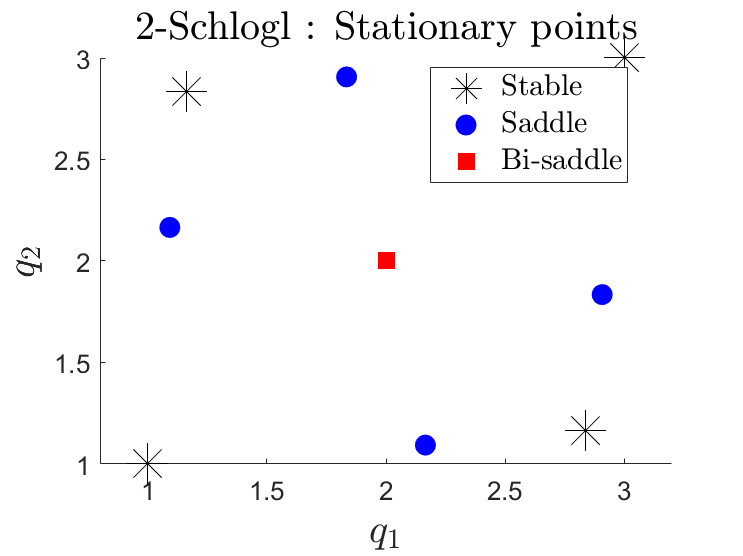

saveas(gcf,'Examples\Plots\'+model_nam+'_stability.png')

## Heteroclinic Network

Data saved in

'Examples\Data\' + model_name + '_hcnet.mat'

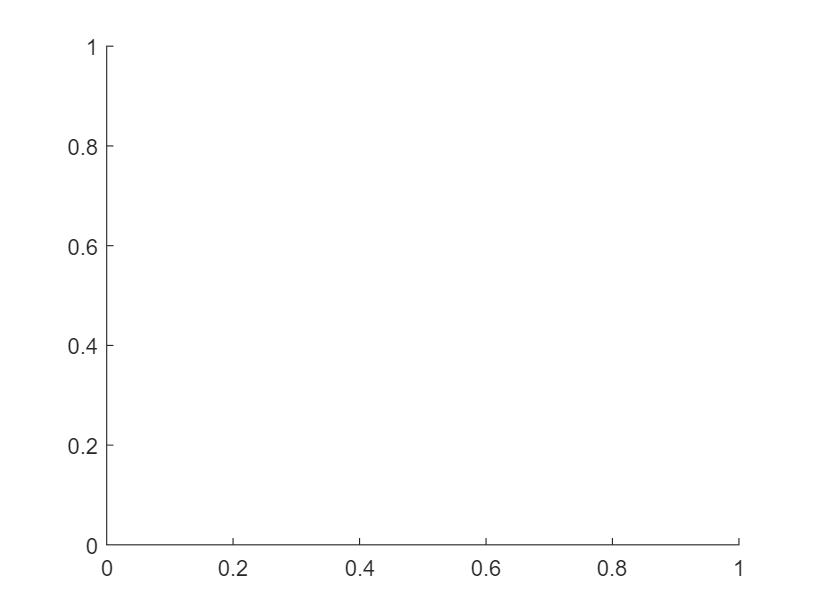

ans = "Computing time"

Unable to perform assignment because the size of the left side is 1-by-1-by-4000-by-2 and the size of the right side is 614-by-2.

Error in test_heteroclinic (line 50)
        hc_traj_arr(i,j,:,:)=sol;

test_heteroclinic